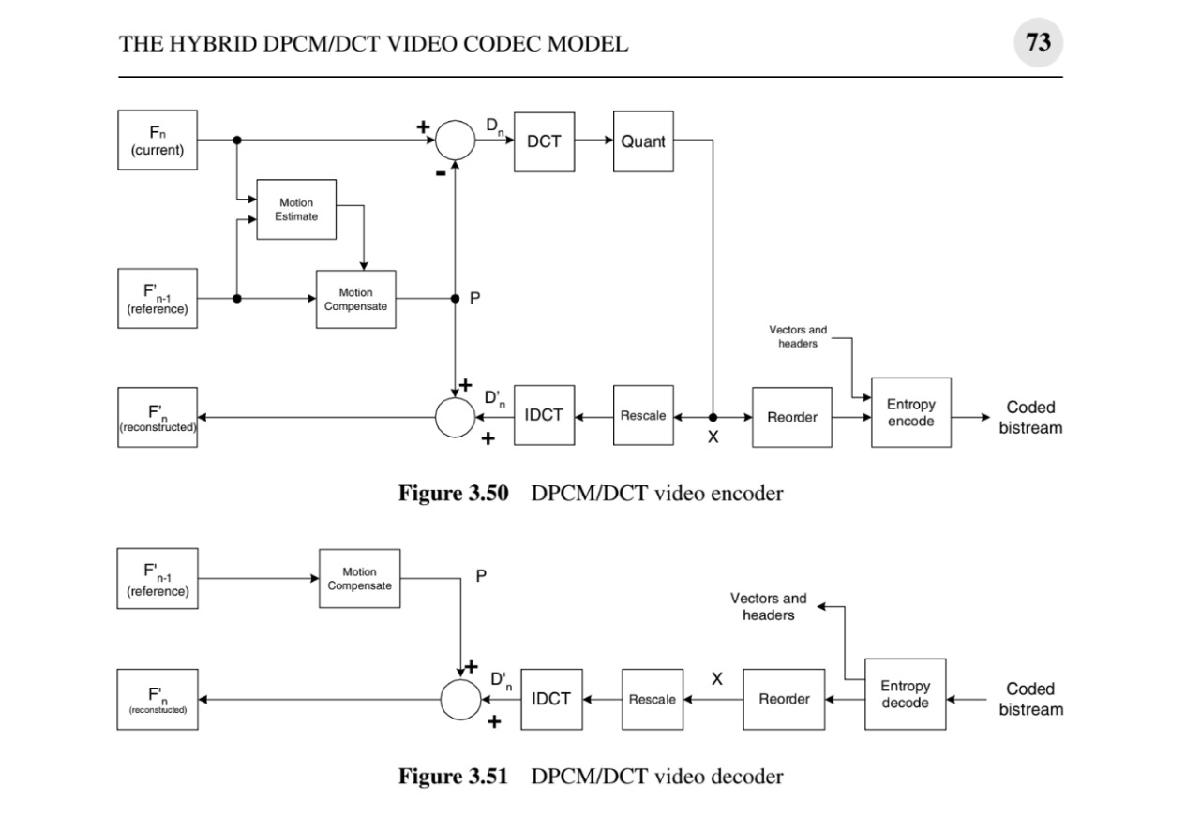

## **Initial Steps:**

- **Reading the video.**

- **Initializing an object for writing the video after decoding.**

- **Setting the frame rate of the object with the video frame rate.**

- **Reading the reference frame and converting it to gray scale.**

- **Encoding the reference frame using JPEG encoder using low or high quantization table.**

- **Decoding the reference frame using JPEG decoder.**

- **Converting the decoded frames of the video into a cell array to be able to write it  in the object video as an output.**

- **ِAssigning the first element in the cell array of the output video by the reference frame.**

- **The first frame is the reference frame for all the upcoming frames along the video.**

clc;
clear all;
close all;
tic

video=VideoReader("xylophone.mp4");    % reading the video
writerObj = VideoWriter('myVideo.avi');  %initializing an object for writing the video after decoding
writerObj.FrameRate = video.FrameRate;


frames= cell(video.NumFrames,1);    % converting the input frames of the video into a cell array 
Ref_Frame=read(video,1);            % reading the reference frame
Ref_Frame=rgb2gray(Ref_Frame);      % converting the frame to gray scale
[rows_len ,col_len]=size(Ref_Frame);
Quantization_type= 1;               % low quantization
[vect,ref_image,dict]=JPEG_encoder(Ref_Frame,Quantization_type);     % encoding the reference frame
predicted_ref = JPEG_decoder(ref_image,dict,rows_len,col_len,Quantization_type);  % decoding the reference frame
Ref_Frame= predicted_ref ;


images= cell(video.NumFrames,1);    % converting the decoded frames of the video into a cell array  
images{1}= predicted_ref;    % assigning the first element in the cell array by the reference frame
num_frames= 1;            % initializing the 1st frame -> it will be increased at the end of every iteration
total_length=0;
open(writerObj);

## **Loop Over all frames: ( starting from the 2nd frame)**

- **Reading frame(i) then converting the frame to gray scale.**

- **Motion estimation: get the difference between each macroblock and bestmatch.**

- **Applying motion estimation on each macroblock of the reference frame(pixel by pixel) using function predict that returns the motion vector. **

- **Applying motion compensation on the reference frame through the function motion_compensation that takes the reference frame and the motion vector then looping on each macroblock(8*8) of the reference frame and detect where to put this macroblock in the predicted frame using the motion vector then returning the predicted frame.**

- **Computing the difference between the current frame and the predicted frame.**

- **Applying JPEG encoder on the difference that includes the runlength encoder.**

- **Converting the motion vector(cell array) into a list to be able to concatenate it with the difference to apply entropy encoding (Huffman) on them together.**

- ** Applying runlength encoder on the motion list.**

for i =2:3 % looping on the frames of the video starting from the 2nd frame
   
frames{i}=read(video,i);     % reading frame(i)
cuFrame=frames{i};          
cuFrame=rgb2gray(cuFrame);   % converting the frame to gray scale

% Motion estimation: get difference between each macroblock and bestmatch
% in difference variable , also it returns motion vector

motionVector =Predict(Ref_Frame,cuFrame,8);    % estimating the current frame motion vector
% motion compensation:
cuFrame= double(cuFrame);
predicted_frame=Motion_compensation(Ref_Frame,motionVector);  % compensating the reference frame to represent the current frame
[len_rows,len_columns]= size(predicted_frame); 

%calculating the difference between the predicted and the current frames
difference= cuFrame - predicted_frame;
[encoded_diff, d,dicto]= JPEG_encoder(difference,Quantization_type);


% converting the motion_vector into a list to be able to encode it:
motion_list=vec2list(motionVector);
Run_length_motion_vector=Run_length_encoder(motion_list); %rulength encoder for the motion list


## **Entropy Encoding:**

- **Concatenating the difference with the motion list into 1 vector (frame_vector).**

- **the 1st and 2nd elements in the frame_vector represents the size of the image in order to be able to know the size of the difference as it is the same size of the image and the size of the motion vector which is equal to the size of the image divided by 8 (macroblock size) without using delimiters.**

- **Extracting the unique symbols with their probabilities using Probability_calculation function.**

- **Applying huffman encoder on the unique symbols.**


frame_vector=[rows_len,col_len,encoded_diff,Run_length_motion_vector]; % concatenating the difference vector and the motion list together
[symbols_low, probabilities_low] = Probability_calculation(frame_vector);   

% applying huffman encoding on the frame vector
dict= huffmanCode(symbols_low,probabilities_low);
encoded_image = huffmanEncoder(frame_vector,dict);

## Decoding Part:

- **Applying Huffman decoder on the output of the Huffman encoder.**

- **Applying runlength decoder on the output of the Huffman decoder.**

before_runlength =huffmanDecoder(encoded_image,dict);       % Huffman decoding
stream_integers =runlength_decoder(before_runlength);       % runlength decoding 

## Extracting the Difference from the transmitted vector:

- **Determine the stop size for the difference using the first 2 elements that represent the size of the image,**

**(stop size = image_length*image_width+2) adding 2 as the first 2 elements of the transmitted frame_vector contain the size so we should exclude them.**

decoded_diff=[];
row_size=stream_integers(1);
col_size=stream_integers(2);
stop_size1=row_size*col_size+2;

for k =3: stop_size1
decoded_diff= [decoded_diff stream_integers(k)];  %Extracting the Difference from the transmitted vector

end

## Extracting the motion vector from the transmitted vector:

        ** 1. Determine the stop size for the motion vector using the first 2 elements that represent the size of the image**

** (stop size = (image_length/8)*(image_width/8)*2), we multiplied by 2 as each motion vector element is (x,y).**

**       2. Converting the motion vector into a cell array again using list2cellA function to be able to do motion compensation.**

stop_size2=(row_size/8)*(col_size/8)*2;
decoded_motionV=[];

for j =stop_size1+1:stop_size1+stop_size2
decoded_motionV= [decoded_motionV stream_integers(j)]; %Extracting the Motion Vector from the transmitted vector
end

motion_vec=list2cellA(decoded_motionV,rows_len/8,col_len/8);  % converting the motion list into a celll array to be able to construct the video




## Motion Compensation part in the decoder:

- **Converting the difference into an image to be able to add it to the output of the motion compensation (predicted frame).**

- **Applying motion compensation on the reference frame using the decoded motion vector to extract the predicted frame.**

- **Adding the difference on the predicted frame. **

- **Then put it in the cell array of the output video.**

recovered_diff= vec2image(decoded_diff,rows_len,col_len,true,Quantization_type);% converting the difference into an image 
predicted_frame=Motion_compensation(predicted_ref,motion_vec); % applying motion compensation for the predicted reference frame
predicted_frame= uint8(predicted_frame);

decoded_frame= predicted_frame+ recovered_diff;  % constructing the decoded current frame

images{i}= decoded_frame;

## Writing the output video:

- **Saving the frame into the output file.**

- **Incrementing the number of frames to use it during calculating the compression ratio.**

- **Incrementing the total length of the encoded frames with the current frame length (output of the Huffman encoder) to use it during calculating the compression ratio.**

- **close the write object of the output video.**

outputFrame = imresize(images{i}, [rows_len, col_len]);
writeVideo(writerObj, outputFrame); % saving the frame into the output file

num_frames= num_frames+1;
total_length=total_length+length(encoded_image);  % calculating the total length of all the vectors coming out from entropy coding
end
close(writerObj);  % close the write object

### Compression ratio:

- **Adding the length of the reference frame( output of the Huffman encoder) to the total length of all frames.**

- **Calculating the compression ratio as follows:**

** image_length*image_width*8*number of frames/ total length of all frames(output of the Huffman encoder)**

total_length=total_length+length(ref_image);
Comp_ratio =compression_ratio(rows_len,col_len,num_frames,total_length);   % calculating the compression ratio
disp("Compression Ratio = " +Comp_ratio);
toc

Compression_ratio (high)  = 8.0997

Elapsed Time (high)= 1690 sec=28 min

///////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////////

### **Evaluation Test:**

**Low compression: 4/5 ->  the quality of the image could be better than that as the compression ratio is low (3.487).**

**High compression: 5/5->  the quality of the image is good compared with the compression ratio (8.0997).**